%%symbols
syms m J c k
syms a1 a2 s1 s2
syms M C K T F Y 
syms y1 y2 y_dot_1 y_dot_2 y_ddot_1 y_ddot_2 F1 F2 
syms theta
syms s

%%Setup of matrix
% m=20;                    % [kg], moving mass in y
% k = 2e4;                 %[Nm/rad],  rotational stiffness
% c = 2;                   %[Nms/rad], rotational damping
% J = 0.1;                 %[kgm2], moment of inertia of the stage
% a1 = 250e-3;             
% a2 = 250e-3;             
% s1 = 25e-3;              
% s2 = 25e-3;             


M=[m 0;
   0 J]

$$M = \left(\begin{array}{cc} m & 0\\ 0 & J \end{array}\right)$$

C=[0 0;
   0 c]

$$C = \left(\begin{array}{cc} 0 & 0\\ 0 & c \end{array}\right)$$

K=[0 0;
   0 k]

$$K = \left(\begin{array}{cc} 0 & 0\\ 0 & k \end{array}\right)$$

F=[1 1;
   -a1 a2]

$$F = \left(\begin{array}{cc} 1 & 1\\ -a_{1} & a_{2} \end{array}\right)$$

T=[1 -s1;
   1 s2]

$$T = \left(\begin{array}{cc} 1 & -s_{1}\\ 1 & s_{2} \end{array}\right)$$


y = [y1; y2]

$$y = \left(\begin{array}{c} y_{1}\\ y_{2} \end{array}\right)$$

y_d = [y_dot_1; y_dot_2]

$$y\_d = \left(\begin{array}{c} {\dot{y}}_{1}\\ {\dot{y}}_{2} \end{array}\right)$$

y_dd = [y_ddot_1; y_ddot_2]

$$y\_dd = \left(\begin{array}{c} {\ddot{y}}_{1}\\ {\ddot{y}}_{2} \end{array}\right)$$


y_l = y;
yd_l = [y1*s; y2*s];
ydd_l = [y1*s^2; y2*s^2];

F_y = [F1; F2]

$$F\_y = \left(\begin{array}{c} F_{1}\\ F_{2} \end{array}\right)$$


M_mod = inv(F)*M*inv(T)

$$M\_mod = \begin{array}{l} \left(\begin{array}{cc} \frac{J}{\sigma_{1}}+\frac{a_{2}\,m\,s_{2}}{\sigma_{1}} & \frac{a_{2}\,m\,s_{1}}{\sigma_{1}}-\frac{J}{\sigma_{1}}\\ \frac{a_{1}\,m\,s_{2}}{\sigma_{1}}-\frac{J}{\sigma_{1}} & \frac{J}{\sigma_{1}}+\frac{a_{1}\,m\,s_{1}}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\left(a_{1}+a_{2}\right)\,\left(s_{1}+s_{2}\right) \end{array}$$

C_mod = inv(F)*C*inv(T)

$$C\_mod = \left(\begin{array}{cc} \frac{c}{\left(a_{1}+a_{2}\right)\,\left(s_{1}+s_{2}\right)} & -\frac{c}{\left(a_{1}+a_{2}\right)\,\left(s_{1}+s_{2}\right)}\\ -\frac{c}{\left(a_{1}+a_{2}\right)\,\left(s_{1}+s_{2}\right)} & \frac{c}{\left(a_{1}+a_{2}\right)\,\left(s_{1}+s_{2}\right)} \end{array}\right)$$

K_mod = inv(F)*K*inv(T) 

$$K\_mod = \left(\begin{array}{cc} \frac{k}{\left(a_{1}+a_{2}\right)\,\left(s_{1}+s_{2}\right)} & -\frac{k}{\left(a_{1}+a_{2}\right)\,\left(s_{1}+s_{2}\right)}\\ -\frac{k}{\left(a_{1}+a_{2}\right)\,\left(s_{1}+s_{2}\right)} & \frac{k}{\left(a_{1}+a_{2}\right)\,\left(s_{1}+s_{2}\right)} \end{array}\right)$$


EOM = M_mod*y_dd + C_mod*y_d + K_mod*y 

$$EOM = \begin{array}{l} \left(\begin{array}{c} {\ddot{y}}_{1}\,\left(\frac{J}{\sigma_{1}}+\frac{a_{2}\,m\,s_{2}}{\sigma_{1}}\right)-{\ddot{y}}_{2}\,\left(\frac{J}{\sigma_{1}}-\frac{a_{2}\,m\,s_{1}}{\sigma_{1}}\right)+\frac{c\,{\dot{y}}_{1}}{\sigma_{1}}-\frac{c\,{\dot{y}}_{2}}{\sigma_{1}}+\frac{k\,y_{1}}{\sigma_{1}}-\frac{k\,y_{2}}{\sigma_{1}}\\ {\ddot{y}}_{2}\,\left(\frac{J}{\sigma_{1}}+\frac{a_{1}\,m\,s_{1}}{\sigma_{1}}\right)-{\ddot{y}}_{1}\,\left(\frac{J}{\sigma_{1}}-\frac{a_{1}\,m\,s_{2}}{\sigma_{1}}\right)-\frac{c\,{\dot{y}}_{1}}{\sigma_{1}}+\frac{c\,{\dot{y}}_{2}}{\sigma_{1}}-\frac{k\,y_{1}}{\sigma_{1}}+\frac{k\,y_{2}}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\left(a_{1}+a_{2}\right)\,\left(s_{1}+s_{2}\right) \end{array}$$


eqns = EOM - F_y == 0 

$$eqns = \begin{array}{l} \left(\begin{array}{c} {\ddot{y}}_{1}\,\left(\frac{J}{\sigma_{1}}+\frac{a_{2}\,m\,s_{2}}{\sigma_{1}}\right)-F_{1}-{\ddot{y}}_{2}\,\left(\frac{J}{\sigma_{1}}-\frac{a_{2}\,m\,s_{1}}{\sigma_{1}}\right)+\frac{c\,{\dot{y}}_{1}}{\sigma_{1}}-\frac{c\,{\dot{y}}_{2}}{\sigma_{1}}+\frac{k\,y_{1}}{\sigma_{1}}-\frac{k\,y_{2}}{\sigma_{1}}=0\\ {\ddot{y}}_{2}\,\left(\frac{J}{\sigma_{1}}+\frac{a_{1}\,m\,s_{1}}{\sigma_{1}}\right)-F_{2}-{\ddot{y}}_{1}\,\left(\frac{J}{\sigma_{1}}-\frac{a_{1}\,m\,s_{2}}{\sigma_{1}}\right)-\frac{c\,{\dot{y}}_{1}}{\sigma_{1}}+\frac{c\,{\dot{y}}_{2}}{\sigma_{1}}-\frac{k\,y_{1}}{\sigma_{1}}+\frac{k\,y_{2}}{\sigma_{1}}=0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\left(a_{1}+a_{2}\right)\,\left(s_{1}+s_{2}\right) \end{array}$$


eqns = subs(eqns, [y y_d y_dd], [y_l, yd_l, ydd_l])

$$eqns = \begin{array}{l} \left(\begin{array}{c} s^{2}\,y_{1}\,\left(\frac{J}{\sigma_{3}}+\frac{a_{2}\,m\,s_{2}}{\sigma_{3}}\right)-F_{1}-s^{2}\,y_{2}\,\left(\frac{J}{\sigma_{3}}-\frac{a_{2}\,m\,s_{1}}{\sigma_{3}}\right)+\frac{k\,y_{1}}{\sigma_{3}}-\frac{k\,y_{2}}{\sigma_{3}}+\sigma_{2}-\sigma_{1}=0\\ s^{2}\,y_{2}\,\left(\frac{J}{\sigma_{3}}+\frac{a_{1}\,m\,s_{1}}{\sigma_{3}}\right)-F_{2}-s^{2}\,y_{1}\,\left(\frac{J}{\sigma_{3}}-\frac{a_{1}\,m\,s_{2}}{\sigma_{3}}\right)-\frac{k\,y_{1}}{\sigma_{3}}+\frac{k\,y_{2}}{\sigma_{3}}-\sigma_{2}+\sigma_{1}=0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{c\,s\,y_{2}}{\sigma_{3}}\\ \sigma_{2}=\frac{c\,s\,y_{1}}{\sigma_{3}}\\ \sigma_{3}=\left(a_{1}+a_{2}\right)\,\left(s_{1}+s_{2}\right) \end{array}$$


eqn2_y2 = solve(eqns(2), y2);
eqn1_sub_y2 = subs(eqns(1), y2, eqn2_y2)

$$eqn1\_sub\_y2 = \begin{array}{l} s^{2}\,y_{1}\,\left(\frac{J}{\sigma_{4}}+\frac{a_{2}\,m\,s_{2}}{\sigma_{4}}\right)-F_{1}+\frac{k\,y_{1}}{\sigma_{4}}-\frac{s^{2}\,\left(\frac{J}{\sigma_{4}}-\frac{a_{2}\,m\,s_{1}}{\sigma_{4}}\right)\,\sigma_{1}}{\sigma_{3}}-\frac{k\,\sigma_{1}}{\sigma_{2}}+\frac{c\,s\,y_{1}}{\sigma_{4}}-\frac{c\,s\,\sigma_{1}}{\sigma_{2}}=0\\ \mathrm{where}\\ \sigma_{1}=F_{2}+s^{2}\,y_{1}\,\left(\frac{J}{\sigma_{4}}-\frac{a_{1}\,m\,s_{2}}{\sigma_{4}}\right)+\frac{k\,y_{1}}{\sigma_{4}}+\frac{c\,s\,y_{1}}{\sigma_{4}}\\ \sigma_{2}=\left(a_{1}+a_{2}\right)\,\left(s_{1}+s_{2}\right)\,\sigma_{3}\\ \sigma_{3}=s^{2}\,\left(\frac{J}{\sigma_{4}}+\frac{a_{1}\,m\,s_{1}}{\sigma_{4}}\right)+\frac{k}{\sigma_{4}}+\frac{c\,s}{\sigma_{4}}\\ \sigma_{4}=\left(a_{1}+a_{2}\right)\,\left(s_{1}+s_{2}\right) \end{array}$$

new_y1 = solve(eqn1_sub_y2, y1)

$$new\_y1 = \begin{array}{l} \frac{F_{1}+\frac{F_{2}\,s^{2}\,\sigma_{3}}{\sigma_{4}}+\frac{F_{2}\,k}{\sigma_{1}}+\frac{F_{2}\,c\,s}{\sigma_{1}}}{s^{2}\,\left(\frac{J}{\sigma_{5}}+\frac{a_{2}\,m\,s_{2}}{\sigma_{5}}\right)+\frac{k}{\sigma_{5}}-\frac{s^{2}\,\sigma_{3}\,\sigma_{2}}{\sigma_{4}}+\frac{c\,s}{\sigma_{5}}-\frac{k\,\sigma_{2}}{\sigma_{1}}-\frac{c\,s\,\sigma_{2}}{\sigma_{1}}}\\ \mathrm{where}\\ \sigma_{1}=\left(a_{1}+a_{2}\right)\,\left(s_{1}+s_{2}\right)\,\sigma_{4}\\ \sigma_{2}=s^{2}\,\left(\frac{J}{\sigma_{5}}-\frac{a_{1}\,m\,s_{2}}{\sigma_{5}}\right)+\frac{k}{\sigma_{5}}+\frac{c\,s}{\sigma_{5}}\\ \sigma_{3}=\frac{J}{\sigma_{5}}-\frac{a_{2}\,m\,s_{1}}{\sigma_{5}}\\ \sigma_{4}=s^{2}\,\left(\frac{J}{\sigma_{5}}+\frac{a_{1}\,m\,s_{1}}{\sigma_{5}}\right)+\frac{k}{\sigma_{5}}+\frac{c\,s}{\sigma_{5}}\\ \sigma_{5}=\left(a_{1}+a_{2}\right)\,\left(s_{1}+s_{2}\right) \end{array}$$

new_y1 = subs(new_y1, [m k c J a1 a2 s1 s2 F1 F2], [20 2e4 2 0.1 250e-3 250e-3 25e-3 25e-3 40 39])

$$new\_y1 = \begin{array}{l} \frac{\frac{3120\,s}{\sigma_{1}}+\frac{31200000}{\sigma_{1}}-\frac{39\,s^{2}}{\sigma_{1}}+40}{80\,s-\frac{800000\,\left(-s^{2}+80\,s+800000\right)}{\sigma_{1}}+9\,s^{2}+\frac{s^{2}\,\left(-s^{2}+80\,s+800000\right)}{\sigma_{1}}-\frac{80\,s\,\left(-s^{2}+80\,s+800000\right)}{\sigma_{1}}+800000}\\ \mathrm{where}\\ \sigma_{1}=9\,s^{2}+80\,s+800000 \end{array}$$

new_y1 = simplify(new_y1)

$$new\_y1 = \frac{321\,s^{2}+6320\,s+63200000}{80\,s^{2}\,\left(s^{2}+20\,s+200000\right)}$$

tf_11 = simplify(new_y1/F1)

$$tf\_11 = \frac{321\,s^{2}+6320\,s+63200000}{80\,F_{1}\,s^{2}\,\left(s^{2}+20\,s+200000\right)}$$

tf_11 = subs(tf_11, F1, 40)

$$tf\_11 = \frac{321\,s^{2}+6320\,s+63200000}{3200\,s^{2}\,\left(s^{2}+20\,s+200000\right)}$$

tf_11 = syms2tf(tf_11)

tf_11 =
 
     321 s^2 + 6320 s + 6.32e07
  ---------------------------------
  3200 s^4 + 64000 s^3 + 6.4e08 s^2
 
Continuous-time transfer function.



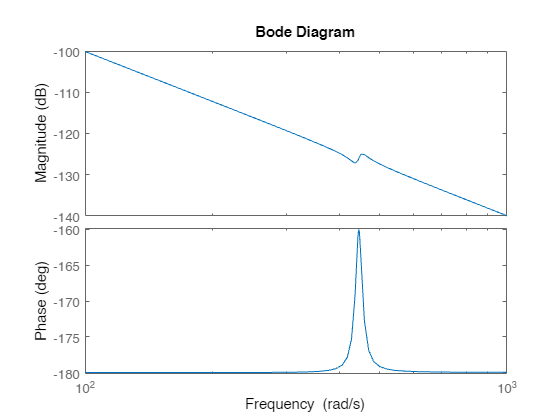


figure;
bode(tf_11)

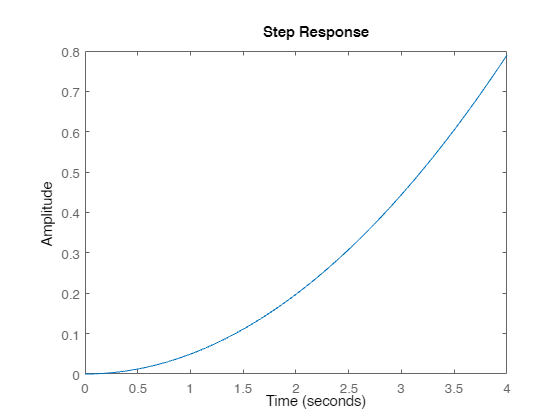

step(tf_11)